N=8;
bit=zeros(N,3);
for i=0:N-1
    bits(i+1, :)=[floor(i/4), mod(floor(i/2),2), mod(i,2)];
end
letters=['r', 'g'];
S=letters(bits + 1)

S = 8×3 char array
    'rrr'
    'rrg'
    'rgr'
    'rgg'
    'grr'
    'grg'
    'ggr'
    'ggg'


R2=S(S(:,2)=='r', :)

R2 = 4×3 char array
    'rrr'
    'rrg'
    'grr'
    'grg'


S=1:6;
E1=S(S>=4)

E1 =      4     5     6


E2=S(mod(S,2)==0)

E2 =      2     4     6


E3=S(mod(sqrt(S), 1)==0)

E3 =      1     4


num_outcomes = length(S);
P_E1=length(E1)/num_outcomes

P_E1 = 0.5000

P_E2=length(E2)/num_outcomes

P_E2 = 0.5000

P_E3=length(E3)/num_outcomes

P_E3 = 0.3333

x1=1:4;
x2=1:4;
for i=1:length(x1)
    for j=1:4
        if j>i
        x=[x1(i),x2(j)]
        end
    end
end

x =      1     2


x =      1     3


x =      1     4


x =      2     3


x =      2     4


x =      3     4


n = 3;
p = 1/3;
k = 0:n;
pmf = factorial(n) ./ (factorial(k).*factorial(n-k)) .* p.^k .* (1-p).^(n-k)

pmf =     0.2963    0.4444    0.2222    0.0370


vec = nchoosek([1 2 3 1 2 3 1 2 3],3)

vec =      1     2     3
     1     2     1
     1     2     2
     1     2     3
     1     2     1
     1     2     2
     1     2     3
     1     3     1
     1     3     2
     1     3     3


S = unique(vec,'rows')

S =      1     1     1
     1     1     2
     1     1     3
     1     2     1
     1     2     2
     1     2     3
     1     3     1
     1     3     2
     1     3     3
     2     1     1


for x = 0:3 % number of red lights
    count = 0;
    for i = 1:size(S,1) % check through sample space
        if nnz(S(i,:) == 1) == x
            count = count + 1;
        end
    end
    p(x+1) = count/size(S,1);
end
p(x+1) = count/size(S,1)

p =     0.2963    0.4444    0.2222    0.0370


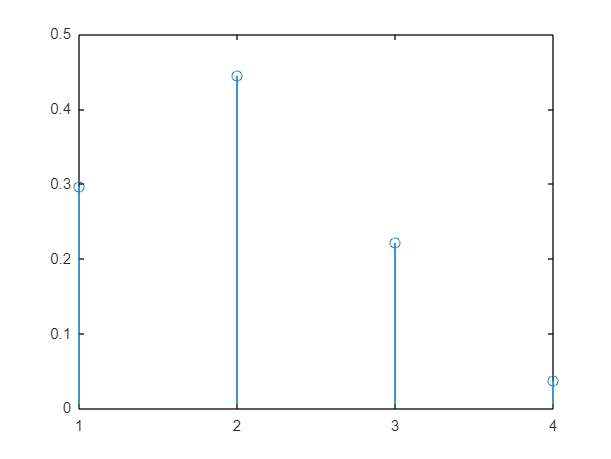

stem(p)